# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                           computeNumericalGradient.m  ex4.mlx                     ex4weights.mat              nnCostFunction.m            sigmoid.m                   token.mat                   
..                          debugInitializeWeights.m    ex4_companion.mlx           fmincg.m                    predict.m                   sigmoidGradient.m           
checkNNGradients.m          displayData.m               ex4data1.mat                lib                         randInitializeWeights.m     submit.m                    



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

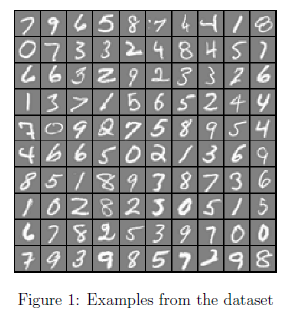

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

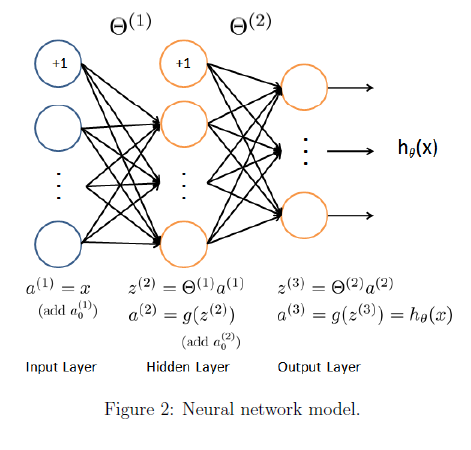

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

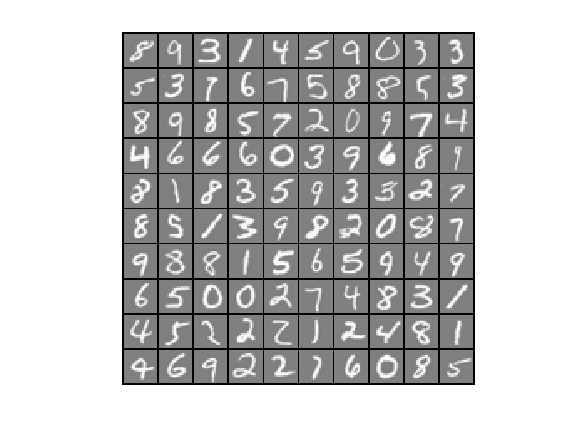

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];


% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_{l+1}$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

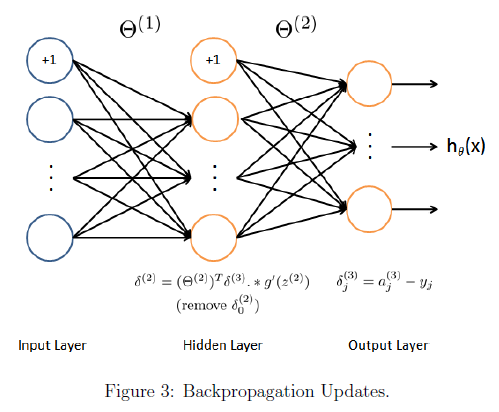

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;

error = 0

J = 0.2876

checkNNGradients(lambda);
% Also output the costFunction debugging value 

Cost at parameters (loaded from ex4weights): 0.287629

% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;


error = 0.0961

J = 0.3838

% Create "short hand" for the cost function to be minimized

Cost at parameters (loaded from ex4weights): 0.383770

costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

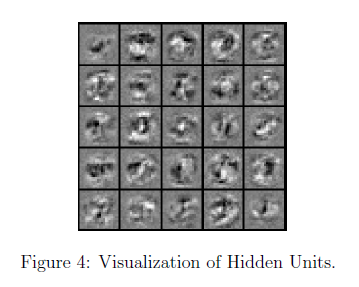

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

ans = 0.2500

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

del1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad =    -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad =     0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad =    -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad =     0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad =    -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad =     0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad =    -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad =     0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad =    -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad =     0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad =    -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad =     0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad =    -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad =     0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad =    -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad =     0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad =    -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad =     0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad =    -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad =     0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad =    -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad =     0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad =    -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad =     0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad =    -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad =     0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad =    -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad =     0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad =    -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad =     0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad =    -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad =     0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0079   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad =    -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad =     0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad =    -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad =     0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad =    -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad =     0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad =    -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad =     0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1505    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0172   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0172   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0172   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0167   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0167   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0397   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0395   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0398   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0398   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0395   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0590    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0590    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0590    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0594    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0592    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0594    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0247    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0249    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0249    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0247    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0250    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0329    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0329    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0326    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0327    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0326    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0601   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0603   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0599   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0603   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0603   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0601   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0323   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0321   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0319   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0321   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0319   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0317   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0317   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0319   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0247   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0247   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0253   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0251   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0249   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0250   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0595    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0598    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0598    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0597    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0595    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0385    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0385    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0391    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0390    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0387    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0173
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0171
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0172
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0172
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0170
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0173
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0578
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0579
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0578
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0577
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0577
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0575
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0451
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0450
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0451
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0451
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0453
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0448
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0449
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0451
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0089
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0088
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0089
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0091
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0091
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0092
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0547


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0548


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0546


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0549


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0548


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0548


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0547


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0649    0.1505    0.0743    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0088   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0079   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0001    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0984    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0082    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0648    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1186    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0084    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0618    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0115    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0650    0.1505    0.0743    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0556    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0026    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110   -0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1085    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0554    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0533    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0001    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0351    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0171    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0336    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0346    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0863    0.1278    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0338    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0970    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2039    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0937    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1477    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0114    0.0972    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0649    0.1505    0.0743    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2041    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0555    0.0614   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1146   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0639   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0079   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1148   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0761    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1277    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0754    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0772    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0245   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0763    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1279    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0195    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0717    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0742    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1256    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0114    0.0971    0.0229    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0057    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0649    0.1505    0.0744    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1258    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1097    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0555    0.0615   -0.0578    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0552    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1095    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0576    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0061    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0550    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0040    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0182    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0328    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0173    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0671    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0169    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0175    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0057    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0746    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0022    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1244    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0774    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0056    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0748    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0649    0.1505    0.0743    0.1271    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1764    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1112   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0641   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0125   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0619   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1114   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1132   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0868    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0382   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0863    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0056    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0861    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0865    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1344    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0801
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0830
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0068   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1322
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0314
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1088    0.0114    0.0971    0.0228    0.0775    0.0338
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2117    0.0649    0.1505    0.0743    0.1271    0.0832
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1324
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0044   -0.0555    0.0615   -0.0577    0.0618   -0.0554
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0065
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0068   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0046
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1038
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0458


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0018


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0533
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0019


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0459


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0017


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0495


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0068   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0014


del1 = 5×4
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


del2 = 3×6
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Theta1_grad = 5×4
   -0.0003   -0.0168   -0.0600   -0.0172
    0.0003    0.0394   -0.0322   -0.0577
   -0.0003    0.0593    0.0252   -0.0450
    0.0003    0.0248    0.0594    0.0090
   -0.0003   -0.0327    0.0390    0.0548


Theta2_grad = 3×6
    0.1029    0.0083    0.0936    0.0196    0.0747    0.0313
   -0.0978   -0.1086    0.0078   -0.1096    0.0124   -0.1039
    0.0995    0.0352    0.0771    0.0183    0.0869    0.0020


Theta1_grad = 5×4
   -0.0040   -0.0171   -0.0602   -0.0170
    0.0035    0.0397   -0.0320   -0.0579
   -0.0029    0.0591    0.0250   -0.0449
    0.0023    0.0249    0.0596    0.0089
   -0.0016   -0.0328    0.0389    0.0549


Theta2_grad = 3×6
    0.2058    0.0617    0.1476    0.0718    0.1245    0.0802
    0.0045   -0.0555    0.0615   -0.0577    0.0618   -0.0553
   -0.0010   -0.0170    0.0244   -0.0327    0.0383   -0.0457


Theta1_grad = 5×4
   -0.0053   -0.0171   -0.0604   -0.0171
    0.0054    0.0398   -0.0318   -0.0578
   -0.0055    0.0591    0.0248   -0.0450
    0.0054    0.0250    0.0599    0.0090
   -0.0052   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.1087    0.0114    0.0971    0.0228    0.0775    0.0337
    0.1067   -0.0025    0.1147   -0.0062    0.1113   -0.0064
    0.0985    0.0345    0.0762    0.0174    0.0864    0.0019


Theta1_grad = 5×4
   -0.0056   -0.0171   -0.0604   -0.0171
    0.0057    0.0397   -0.0318   -0.0578
   -0.0058    0.0591    0.0248   -0.0450
    0.0057    0.0250    0.0599    0.0090
   -0.0054   -0.0328    0.0386    0.0547


Theta2_grad = 3×6
    0.2116    0.0649    0.1504    0.0743    0.1270    0.0831
    0.0089   -0.0534    0.0640   -0.0551    0.0642   -0.0534
    0.1979    0.0862    0.1278    0.0672    0.1343    0.0496


Theta1_grad = 5×4
   -0.0093   -0.0168   -0.0602   -0.0174
    0.0089    0.0394   -0.0320   -0.0576
   -0.0084    0.0593    0.0249   -0.0452
    0.0076    0.0248    0.0598    0.0091
   -0.0067   -0.0327    0.0386    0.0546


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0016


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

del1 = 25×401
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

del2 = 10×26
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0   

Theta1_grad = 25×401
   -0.0001   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0019   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0006   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0005   -0.0009   -0.0005   -0.0004    0.0004   -0.0016    0.0003    0.0003    0.0015   -0.0015   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0001   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0032   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0006   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0005   -0.0009   -0.0005   -0.0004    0.0004   -0.0016    0.0003    0.0003    0.0015   -0.0015   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0001   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0043   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0006   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0015   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0001   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0047   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0015   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0055   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0015   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0070   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0009    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0036   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0080   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0018    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0034   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0116   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0002   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0019    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0034   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0133   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0019   -0.0001    0.0008    0.0006   -0.0009   -0.0005   -0.0004    0.0004   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0010    0.0007   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0006   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0003   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0167    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0170   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0156   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0010    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0003   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0215    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0162   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0003   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0215    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0170   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
   -0.0004   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0217    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0175   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005   -0.0000   -0.0002    0.0008   -0.0009   -0.0006   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0015    0.0009
    0.0000   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0012   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0217    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0209   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0012   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0218    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0234   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0015   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0238    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0248   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0011   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0015   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0237    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0249   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0015   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0237    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0249   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0012   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0275    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0266   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0012   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0295    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0270   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0017   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0295    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0276   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0008    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0017   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0308    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0304   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0017   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0310    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0169   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0308   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0047   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0355    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0171   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0346   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0044   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0442    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0170   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0359   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0044   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0442    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0170   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0366   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0245   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0485    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0175   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0443   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0251   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0511    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0172   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0450   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0000    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0248   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0554    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0171   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0452   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0248   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0555    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0171   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0475   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0300   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0563    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0525   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0300   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0563    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0526   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0015   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0300   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0564    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0526   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0313   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0564    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0543   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0313   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0564    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0544   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0566    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0557   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0567    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0565   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0565   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0565   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0565   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0014   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0311   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0565   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0310   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0566   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0310   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0569    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0567   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0326   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0570    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0611   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0326   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0585    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0611   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0325   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0585    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0611   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0325   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0585    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0619   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0339   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0585    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0629   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0005   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0338   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0588    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0630   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0306   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0594    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0637   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0307   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0594    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0641   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0308   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0596    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0642   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0307   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0003   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0596    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0134
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0643   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0392   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0599    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0658   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0394   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0617    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0659   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0005    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0394   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0618    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0662   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0002    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0396   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0620    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0744   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0000   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0002    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0432   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0620    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0179   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0785   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0432   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0626    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0786   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0435   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0627    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0818   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0006    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0440   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0638    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0184   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0821   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0440   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0639    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0185   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0828   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0450   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0639    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0185   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0839   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0449   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0643    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0184   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0855   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0495   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0645    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0184   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0869   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0495   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0645    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0870   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0510   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0645    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0909   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0510   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0647    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0909   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0510   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0658    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0909   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0546   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0658    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0918   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0545   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0673    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0934   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0005    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0556   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0673    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0939   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0556   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0687    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0939   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0556   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0690    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0939   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0556   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0692    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0939   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0589   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0697    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0998   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0589   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0696    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0998   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0589   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0700    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.0999   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0006   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0589   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0777    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1000   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0588   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0799    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1007   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0012   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0601   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0799    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0180   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1009   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0001    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0601   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0802    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1009   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0600   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0810    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1010   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0600   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0812    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1010   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0011   -0.0011   -0.0002    0.0002   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0598   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0843    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1012   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0630   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0843    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1044   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0001    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0636   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0847    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0181   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1052   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0002   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0014    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0757   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0868    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1057   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.0757   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0878    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0182   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1058   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1018   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0896    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0211   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1107   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1037   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0899    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0211   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1117   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0011   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1039   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0904    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0211   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1150   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1045   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0970    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0216   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1157   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1046   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0984    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0216   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1158   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0018   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1081   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0998    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0217   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1168   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1087   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.0998    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0217   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1182   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0005   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0007    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1151   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1002    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0218   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1202   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0006    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1133   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1073    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0215   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1211   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0006    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1129   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1262    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0212   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1211   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0006    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1138   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1262    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0215   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1258   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0004   -0.0001   -0.0012   -0.0006    0.0006    0.0003    0.0015   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1143   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1263    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0215   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1284   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1133   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1698    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0204   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1284   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1133   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1699    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0204   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1287   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1248   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1792    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0211   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1372   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0008   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1279   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1930    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0298   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1460   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1286   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1939    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0304   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1493   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1286   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1950    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0304   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1495   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1282   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.1986    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0304   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1495   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1281   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2013    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0303   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1495   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1277   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2188    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0299   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1496   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1277   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2192    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0299   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1496   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1278   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2193    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0298   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1504   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0001   -0.0012    0.0012   -0.0017   -0.0000    0.0009    0.0007   -0.0009   -0.0005   -0.0003    0.0005   -0.0015    0.0003    0.0003    0.0015   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0003   -0.0005    0.0007   -0.0003
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1278   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2808    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1538   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1278   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.2811    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1541   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0003    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1334   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3058    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1602   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0001    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1336   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3058    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1604   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1337   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3058    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1604   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1338   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3058    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1605   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1340   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3058    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0954   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1608   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1337   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3065    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0981   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1613   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0014   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1337   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3087    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0979   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1616   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1426   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3089    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0979   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1623   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1426   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3089    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1623   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1426   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3089    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1624   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0001   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1478   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3089    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1628   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0009   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0008   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1478   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3089    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1628   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1478   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3097    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1630   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0002   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1478   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3097    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1630   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1478   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3097    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.0980   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1648   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1500   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3098    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1016   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1654   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1500   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3098    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1016   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1659   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0017    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0002    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1694   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3100    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1060   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1673   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.1696   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3100    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1060   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1682   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0000    0.0003    0.0004   -0.0001    0.0012   -0.0001   -0.0011    0.0003    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0004   -0.0010    0.0001   -0.0

Theta1_grad = 25×401
    0.2079   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3101    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1213   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1663   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2079   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3103    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1214   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1663   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0013   -0.0004    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2142   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3115    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1214   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1732   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2141   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3118    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1214   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1732   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2141   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3119    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1214   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1734   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2154   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3119    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1214   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1740   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2155   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3118    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1217   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1746   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2231   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3127    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1217   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1765   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2232   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3127    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1217   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1776   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0005    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2678   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3181    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1485   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1926   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2680   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3181    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1485   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1927   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2679   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3202    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1485   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1927   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0002    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2679   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3202    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1485   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1928   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2695   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3203    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1485   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1941   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2698   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3205    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1487   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1981   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2698   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3228    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1487   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1981   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.2700   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0016    0.0009    0.0015    0.0004   -0.0004   -0.0001    0.0003    0.0007    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0003    0.0013    0.0056    0.0090    0.0044
    0.3228    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0006   -0.0006    0.0001    0.0016    0.0005   -0.0003   -0.0004    0.0005   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001   -0.0009   -0.0018   -0.0085   -0.0296   -0.0135
   -0.1487   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0005   -0.0006    0.0002    0.0002    0.0006    0.0001    0.0013    0.0038   -0.0032   -0.0072   -0.0002    0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0039    0.0095   -0.0046   -0.0133   -0.0040
   -0.1982   -0.0000    0.0000   -0.0000   -0.0000    0.0006    0.0054   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0002    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0009    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002   -0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0013    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0009
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0008    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0004   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0008   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0016   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0007   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0004   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0001    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0002    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0003   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0002    0.0010    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0003   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0009   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0000    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0006    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0005    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0005    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0010   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0005    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0005    0.0006    0.0004    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0014   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0011   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0015   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0015   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0003    0.0004   -0.0007    0.0015   -0.0003    0.0002    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0010    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0016    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0010   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0004    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0001    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0003    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0002   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0012    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0003   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0003   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0003   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0001    0.0003    0.0004   -0.0000    0.0012   -0.0001   -0.0011    0.0004    0.0006   -0.0020    0.0009    0.0003   -0.0005   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0013   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0017   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0003   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0010   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0009   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0002    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0001    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0002   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005   -0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0015   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0005   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0017   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0005    0.0018   -0.0011    0.0010
    0.0004   -0.0012    0.0013   -0.0015    0.0002    0.0011    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0008    0.0011   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0010   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0004    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0015    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0003    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0003    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0005   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0010   -0.0009   -0.0005    0.0000    0.0005   -0.0015    0.0003    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0006   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0005    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0008   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0003    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0011   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0012   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0010   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0009   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0012    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0007    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0014    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0018   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0002    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0011   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0011    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0001    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0002   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0002    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0002    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0012    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0016   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0006   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0005    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0001   -0.0001   -0.0009   -0.0004    0.0006    0.0006    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0004    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0012   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0004    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0013   -0.0006   -0.0009   -0.0008   -0.0001    0.0007   -0.0001    0.0012   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0014   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0013    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0004   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011   -0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0013    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0012   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0004    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0019   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0001    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0011   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0000    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0000    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0017   -0.0000    0.0005    0.0003    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0006    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0010    0.0010
    0.0007   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0009   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0001   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0009   -0.0003    0.0006    0.0007    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0001    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0000   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0002    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0003   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0011    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0005    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0008   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0008   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0013   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018   -0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0014   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009   -0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0011   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0006    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0004    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0005    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0016   -0.0014   -0.0005    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0006   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0006    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0008   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0000   -0.0007   -0.0001   -0.0014   -0.0006   -0.0013    0.0003    0.0007    0.0013    0.0003   -0.0007    0.0006   -0.0010    0.0008    0.0008    0.0010   -0.0001   -0.0009    0.0007    0.0001   -0.0002   -0.0004   -0.0001   -0.0013   -0.0004   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0007    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0002   -0.0008   -0.0001   -0.0014   -0.0007   -0.0014    0.0002    0.0007    0.0013    0.0001   -0.0007    0.0005   -0.0011    0.0007    0.0007    0.0010   -0.0002   -0.0010    0.0005    0.0000   -0.0002   -0.0004   -0.0002   -0.0014   -0.0005   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0007    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0002   -0.0008   -0.0001   -0.0014   -0.0007   -0.0014    0.0002    0.0007    0.0013    0.0001   -0.0007    0.0005   -0.0011    0.0006    0.0007    0.0010   -0.0002   -0.0010    0.0005    0.0000   -0.0002   -0.0004   -0.0002   -0.0014   -0.0005   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0011    0.0001   -0.0001   -0.0008   -0.0003    0.0007    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0002   -0.0008   -0.0001   -0.0014   -0.0007   -0.0014    0.0002    0.0007    0.0013    0.0001   -0.0007    0.0005   -0.0011    0.0006    0.0007    0.0010   -0.0002   -0.0010    0.0005    0.0000   -0.0002   -0.0004   -0.0002   -0.0014   -0.0005   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0010    0.0001   -0.0000   -0.0008   -0.0003    0.0007    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0002   -0.0008   -0.0001   -0.0014   -0.0007   -0.0014    0.0002    0.0007    0.0013    0.0001   -0.0007    0.0005   -0.0011    0.0006    0.0007    0.0010   -0.0002   -0.0010    0.0005    0.0000   -0.0002   -0.0004   -0.0003   -0.0014   -0.0005   -0.0008
    0.0007    0.0005   -0.0007    0.0018    0.0000    0.0006    0.0004    0.0009   -0.0009    0.0000   -0.0013   -0.0016   -0.0012    0.0012    0.0003    0.0012   -0.0010    0.0001   -0.0000   -0.0008   -0.0003    0.0007    0.0008    0.0020   -0.0009    0.0010
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0003   -0.0008   -0.0001   -0.0015   -0.0007   -0.0015    0.0001    0.0007    0.0012   -0.0000   -0.0007    0.0004   -0.0012    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0004   -0.0004   -0.0015   -0.0005   -0.0009
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0003    0.0012   -0.0010    0.0001   -0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0009    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0004    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0003   -0.0008   -0.0001   -0.0015   -0.0007   -0.0015    0.0001    0.0007    0.0012   -0.0000   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0004   -0.0004   -0.0015   -0.0005   -0.0009
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001   -0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0009    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0003   -0.0008   -0.0001   -0.0015   -0.0007   -0.0015    0.0000    0.0007    0.0012   -0.0000   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0004   -0.0004   -0.0015   -0.0005   -0.0009
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001   -0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0009    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0003   -0.0008   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0007    0.0012   -0.0000   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0004   -0.0004   -0.0015   -0.0005   -0.0009
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0009    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0003   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0005    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009   -0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0006    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0012    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0005    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0013   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0001    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015    0.0000    0.0006    0.0012   -0.0001   -0.0007    0.0004   -0.0013    0.0005    0.0005    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015   -0.0000    0.0006    0.0011   -0.0001   -0.0007    0.0004   -0.0013    0.0004    0.0005    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0004   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0009   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0008   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0009   -0.0002   -0.0015   -0.0007   -0.0015   -0.0000    0.0006    0.0011   -0.0001   -0.0007    0.0004   -0.0013    0.0004    0.0005    0.0008   -0.0003   -0.0010    0.0004    0.0000   -0.0002   -0.0005   -0.0005   -0.0015   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0008   -0.0011    0.0013   -0.0012    0.0005    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0014    0.0004    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0001   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0016   -0.0001    0.0006    0.0011   -0.0002   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0008   -0.0003   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0012   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0006    0.0011   -0.0002   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0008   -0.0003   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0006    0.0011   -0.0002   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0008   -0.0003   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0005    0.0011   -0.0002   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0008   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0000    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0016   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0005    0.0011   -0.0002   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0008   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0009   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0005    0.0011   -0.0003   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0007   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0005    0.0011   -0.0003   -0.0008    0.0002   -0.0015    0.0003    0.0003    0.0007   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0003    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0001    0.0005    0.0011   -0.0003   -0.0008    0.0001   -0.0015    0.0003    0.0003    0.0007   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0004    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0002    0.0005    0.0011   -0.0003   -0.0008    0.0001   -0.0015    0.0003    0.0003    0.0007   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0004    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0006   -0.0010   -0.0003   -0.0015   -0.0009   -0.0017   -0.0002    0.0005    0.0011   -0.0003   -0.0008    0.0001   -0.0015    0.0003    0.0003    0.0007   -0.0004   -0.0010    0.0002    0.0000   -0.0002   -0.0006   -0.0005   -0.0017   -0.0006   -0.0010
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0004    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

Theta1_grad = 25×401
    0.0010   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.

Theta2_grad = 10×26
   -0.0008   -0.0011   -0.0004   -0.0016   -0.0010   -0.0017   -0.0003    0.0005    0.0011   -0.0005   -0.0010   -0.0000   -0.0017    0.0003    0.0002    0.0006   -0.0005   -0.0011   -0.0000   -0.0000   -0.0003   -0.0008   -0.0007   -0.0018   -0.0008   -0.0011
    0.0008    0.0005   -0.0007    0.0019    0.0001    0.0006    0.0005    0.0009   -0.0009    0.0001   -0.0013   -0.0015   -0.0011    0.0013    0.0004    0.0013   -0.0010    0.0001    0.0000   -0.0008   -0.0003    0.0007    0.0009    0.0021   -0.0008    0.0011
    0.0009   -0.0011    0.0014   -0.0012    0.0006    0.0014    0.0014   -0.0008   -0.0004    0.0004    0.0006   -0.0013    0.0005    0.0005    0.0017   -0.0014   -0.0005    0.0015   -0.0005   -0.0008   -0.0007   -0.0000    0.0009    0.0000    0.0014   -0.0002
    0.0002    0.0004    0.0004    0.0001    0.0013   -0.0001   -0.0011    0.0004    0.0007   -0.0020    0.0009    0.0003   -0.0004   -0.0015    0.0006   -0.0003   -0.0002   -0.0009    0.0002   -0.0

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

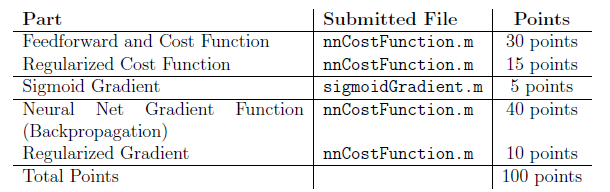

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.